## Clear memory and set path

clearvars; close all; clc
home = pwd; cd ..; cd ..; base = pwd; cd(home);
addpath(fullfile(base,'CoFE_toolbox'))

## CASE data

%from the tenbar.bdf example
%1/adapt to our problem

inputFile = 'twoBeam_analysis2.bdf';
CASE = case_obj;
CASE.SOL = 101;
CASE.SPC = 100;
CASE.LOAD = 88;
CASE.STRESS = 1;
CASE.STRAIN = 1;
CASE.ESE = 1;
CASE.EKE = 1;
CASE.PRINT = 1;

%for geometric properties
%https://skyciv.com/fr/free-moment-of-inertia-calculator/
%https://structx.com/Shape_Formulas_031.html


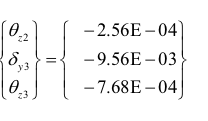

%2/any vibration?
% CASE.METHOD = 30;
% CASE(2) = CASE(1);
% CASE(2).SOL = 103;
% 

## Run CoFE

FEM = CoFE_analysis(inputFile,CASE);

Error using fgets
Invalid file identifier. Use fopen to generate a valid file identifier.

Error in fgetl (line 32)
[tline,lt] = fgets(fid);

Error in importData>nextLine (line 71)
A = fgetl(fid);

Error in 

## Post process

CoFE2_view(FEM);
%view(0,0)
% axis([-50 850 -1 1 -500 125])
% axis equal